# Regression model for A549

**Summary:**

- Take one cell line (ie A549)

- Plot the raw z-score of the histone markers for A549

- Compute the fluxes in multiple medium conditions and compute correlation between metabolic fluxes and histone proteomics data

- Save the log10 model regression coefficients

- Use the regression coefficients to compute the predicted proteomics given the new metabolic fluxes 

## Set histone reaction upper bound to reflect the maximum number of histone sites in a given cell

The idea is to maximize the flux of the histone reactions based on the total number of potential histone modification sites. This is used as a physical constraint in the metabolic model by setting the upper bound in the constraint problem. 

**RESULT:**

- When I ran flux balance analysis for all medium analyses, the computed flux for all markers was the maximum (1.7uM/gDW). Thus, it won't be useful if I inputted this into a regression model.

initCobraToolbox
changeCobraSolver('gurobi');

load 10282019eGEM.mat

% the maximum flux through histone reactions = 0.0017mM/gDW or 1.7uM/gDW
%maxHistoneUB = 1.7;
%histoneReactionPositions = [3752, 3759, 3760, 3761];
%eGEM.ub(histoneReactionPositions) = maxHistoneUB;

% If this doesn't work
oldHistoneUB = 100;
histoneReactionPositions = [3752, 3759, 3760, 3761];
eGEM.ub(histoneReactionPositions) = oldHistoneUB;

## Plot the raw z-score of the histone markers for A549

Just for my own sanity, I wanted to see what the response variable looks like for what I'm predicting. The heatmap shows the raw z-scores used for A549, which is the cancer cell line I will be predicting.

[cell_names, medium, marks, proteomics] = load_proteomics('CCLE');
cellLine                                = 'A549';
ProteomicsPositions = find(ismember(string(cell_names), ...
        string(cellLine)));
A549proteomics                          = proteomics(ProteomicsPositions, :);
A549medium                              = medium(ProteomicsPositions, :);

figure;
heatmap(A549proteomics, ...
    'XData',    marks, ...
    'YData',    'A549', ...
    'Colormap', redbluecmap);
title('Raw Z-scores for A549 proteomics data');

## Compute the fluxes in multiple medium conditions and compute correlation between metabolic fluxes and histone proteomics data

Before using the linear regression models to predict the histone marker z-scores, I need to compute the flux values in different medium conditions, as I want to predict how metabolic conditions impact histone markers. 

I computed the metabolic fluxes for various medium described in the Cancer Cell Line Encylopedia, and the list is shown below.

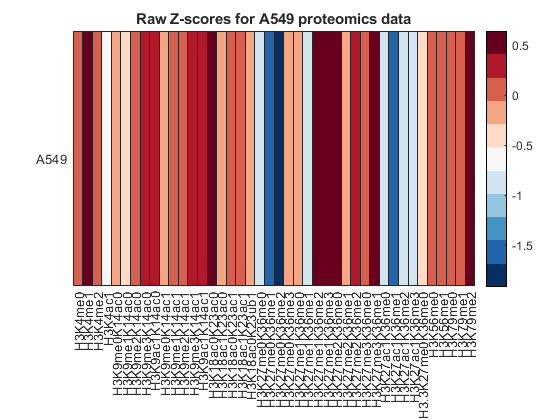

load ccle_geneExpression_vars.mat
load allVars.mat

model = eGEM;

kappa       = 1;
pearson     = 1;
epsilon     = 1E-3;
mode        = 1;
epsilon2    = 1E-3;
minfluxflag = 1;


RNAPositions = find(ismember(string(celllinenames_ccle1), ...
        string(cellLine)));
A549Transcriptomics = ccle_expression_metz(:, RNAPositions);

ON_fieldname  = string(strcat('ON_', cellLine));
OFF_fieldname = string(strcat('OFF_', cellLine));
diffExpGenes  = findDiffExpGenes(model, RNAPositions);

histoneReactions  = ["DM_KAC"; "DM_KMe1"; "DM_KMe2"; "DM_KMe3"];
reactionPositions = [find(ismember(model.rxns,...
    histoneReactions))];

uniqueMedium = unique(medium);
for i = 1:length(uniqueMedium)
    oneMedium = string(uniqueMedium(i));
    
    str = strcat('ObjCoef = epsilon2_', lower(oneMedium), '(:, 1);');
    eval(str);
    
    constrainedModel   = medium_LB_constraints(model, uniqueMedium); 
    constrainedModel.c = zeros(size(constrainedModel.c));
    constrainedModel.c(reactionPositions) = ObjCoef;
    
    [~, solution] =  CFR...
        (constrainedModel, diffExpGenes.(ON_fieldname), ...
        diffExpGenes.(OFF_fieldname), ...
        kappa, pearson, epsilon, mode, [], minfluxflag);
    A549Fluxes(i, :) = solution.flux;
    
end 

clearvars -except fluxSolution medium A549proteomics marks;
unique(medium)

## Training the linear regression model

To run linear regression, I wanted to train and test two different models:

- Train a linear regression model using all cancer cell line data. Because there are ~ 31 different medium components, I can allow for ~ 150 cancer cell lines to train on based on an 80/20 train/test split.

- Train a linear regression model using only melanoma cell line data. This, I believe, will show better metrics of model fit and thus prediction.

### All cancer cell line data model

- The model containing the 69 writer genes performed the best overall, compared to all histone readers/writers/erasers, Ac and Me readers/writers, and Ac/Me erasers only.

- The histone reactions only model was better performing model compared to inclusion of other fluxes, so I chose that as the dataset to train on.

- A log transformation of the Z-scaled data set resulted in more signficant hits, and that operation was performed in the training and testing dataset.

- The flux data in the table was derived from competition flux balance analysis, where there were 5 objectives competing for each other (1 biomass objective + 4 histone reaction objectives). 

writers = readtable('CCLECompModelMeAcWriters.csv', ...
    'ReadVariableNames', true, ...
    'ReadRowNames', true);

#### Standardize the entire dataset

- The entire dataset was first z-scaled then log transformed. The reason why I did it this was was because the CCLE GCP dataset (histone proteomics expression) was already Z-transformed. Thus, to have all of the data on the same scale, I first transformed the gene expression and flux to z-scores, then log-transformed all scores after making all z-scores > 0. 

cellLines = writers.Properties.RowNames;
features  = writers.Properties.VariableNames;

% Split into gene expression, histone proteomics, and reaction sets
genes             = features(:, 1:69);
geneExpression    = writers(:, 1:69);
histoneMarkers    = features(:, 70:111);
histoneProteomics = writers(:, 70:111);
reactions         = features(:, 112:end);
histoneReactions  = writers(:, [3863, 3870, 3871, 3872]);

% Z-scale the training data
[~, scaledA549Fluxes]    = posZscale(geneExpression, 'raw');
[~, scaledHistFlux] = posZscale(histoneReactions, 'raw');
[~, scaledProt]     = posZscale(histoneProteomics, 'zscore');

% Log10 transformation the training data
logScaledGenes    = varfun(@log, scaledA549Fluxes);
logScaledHistFlux = varfun(@log, scaledHistFlux);
logProtNorm       = varfun(@log, scaledProt);

#### Make test set

- The test set comprises of all A549 gene expression, flux, and histone proteomics data. The flux data is from 31 different medium conditions, and so I kept the same gene expression and histone proteomics data, but expanded those datasets using `repmat` so I can construct matricies with the dimensions 34 x N predictors/responses.

- The flux data was treated with the same standardization and log transformation described above.

- NaNs were turned to 0 to run the regression model.

% Need to load the medium fluxes for A549
A549Fluxes  = A549Fluxes(:, [3752, 3759, 3760, 3761]);

% Standardize
[~, scaledA549Fluxes]    = posZscale(A549Fluxes, 'raw');
logScaledA549Fluxes      = varfun(@log, scaledA549Fluxes);

% Create test set
testGenes = logScaledGenes('A549', :);
testGenes = table2array(testGenes);
testGenes = repmat(testGenes, size(logScaledA549Flux, 1), 1);

testProt = logProtNorm('A549', :);
testProt = table2array(testProt);
testProt = repmat(testProt, size(logScaledA549Flux, 1), 1);

Xtest = [testGenes, table2array(logScaledA549Flux)];
ytest = testProt

Xtest(isnan(Xtest)) = 0;
ytest(isnan(ytest)) = 0;

#### Make training set

- To have 20% test 80% training, I took 150 random cancer cell lines for the training set. 

Xtrain = [logScaledGenes, logScaledHistFlux];
ytrain = logProtNorm;

Xtrain = table2array(Xtrain);
ytrain = table2array(ytrain);

% Get only 150 observations
[Xtrain, idx] = datasample(Xtrain, 150, 'Replace', false);
ytrain = ytrain(idx', :);

Xtrain(isnan(Xtrain)) = 0;
ytrain(isnan(ytrain)) = 0;

## Linear regression on the data

For this part, I reported the hold-out MSE. This is because I have a separate test set than the training set, and the test set is pretty small (N = 31). Thus, I don't think cross-validation would have been a good strategy.

for i = 1:size(ytrain, 2)
    mdl = fitlm(Xtrain, ytrain(:, i));
    yfit(:, i) = predict(mdl, Xtest);
    yfit(:, i) = normalize(yfit(:, i), 'zscore');
    MSE(i) = sum((ytest(:, i) - yfit(:, i)).^2)/size(ytest, 2);
    adjR2(i) = mdl.Rsquared.Adjusted;
end

#### Figure showing the expression / medium prediction in a heatmap

The main takeaway from this figure is that the H3K27 markers generally have low MSE and high adjusted R2, suggesting that these are reliable predictions. The heatmap shows the medium components 

figure;

% Heatmap showing the raw proteomics data versus the outputed prediction
% Z-score normalized
columnNames = ['A549 Proteomics'; unique(medium)];
heatmap([A549proteomics; yfit], ...
    'XData', marks, ...
    'YData', columnNames, ...
    'Colormap', redbluecmap);
xlabel('Histone Markers');

#### Figure showing the expression / medium prediction in a clustergram

data = [A549proteomics; yfit];
cgo = clustergram(data, ...
    'Colormap', redbluecmap, ...
    'Standardize','Row');
set(cgo, ...
    'RowLabels', columnNames, ...
    'ColumnLabels', marks);

#### Figure showing the expression / medium component prediction in a heatmap

The main takeaway from this figure is that the H3K27 markers generally have low MSE and high adjusted R2, suggesting that these are reliable predictions. The heatmap shows the medium components 

figure;

% Heatmap showing the raw proteomics data versus the outputed prediction
% Z-score normalized
columnNames = ['A549 Proteomics'; allMediumComponents];
heatmap([A549proteomics; yfit], ...
    'XData', marks, ...
    'YData', columnNames, ...
    'Colormap', redbluecmap);
xlabel('Histone Markers')